% Initialize symbols 
syms M m1 m2 l1 l2 g F t1 t2 x x_ t1_ t2_;

% Setup the functions after small angle approximation 
X_dotdot =(F - m1*g*t1 - m2*g*t2)/M;
t1_dotdot = (F - m1*g*t1 - m2*g*t2 - M*g*t1)/(M*l1);
t2_dotdot = (F - m1*g*t1 - m2*g*t2 - M*g*t2)/(M*l2);

% Setup state and input vectors
X_states = [x x_ t1 t1_ t2 t2_];
X_eq = [x_ X_dotdot t1_ t1_dotdot t2_ t2_dotdot];
U_input = F;

% Programmatically attain A matrix through Jacobian linearization
A_ = zeros(length(X_eq), length(X_states)) + x;
for i = 1:length(X_eq)
    for j = 1:length(X_states)
        A_(i, j) = diff(X_eq(i), X_states(j));
    end
end
disp(A_)

$$\left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -\frac{g\,m_{1}}{M} & 0 & -\frac{g\,m_{2}}{M} & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{M\,g+g\,m_{1}}{M\,l_{1}} & 0 & -\frac{g\,m_{2}}{M\,l_{1}} & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\frac{g\,m_{1}}{M\,l_{2}} & 0 & -\frac{M\,g+g\,m_{2}}{M\,l_{2}} & 0 \end{array}\right)$$


% Programmatically attain B matrix through Jacobian linearization
B_ = zeros(length(X_states), length(U_input)) + x;
for i = 1:length(U_input)
    for j = 1:length(X_eq)
        B_(j, i) = diff(X_eq(j), U_input(i));
    end
end
disp(B_)

$$\left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ \frac{1}{M\,l_{1}}\\ 0\\ \frac{1}{M\,l_{2}} \end{array}\right)$$


n = size(A_, 1); 

% Set Initial Condition
X0 = [0 ; 0.1 ; 10 ; 0.2 ; 5 ; 0.3];

% Set System Parameters
M_v = 1000;
m1_v = 100;
m2_v = 100;
l1_v = 20;
l2_v = 10;
g_v = 9.8;

% Substitute System Parameters into Symbolic Matrices
A = double(subs(A_, {M m1 m2 l1 l2 g}, {M_v m1_v m2_v l1_v l2_v g_v}))

A =          0    1.0000         0         0         0         0
         0         0   -0.9800         0   -0.9800         0
         0         0         0    1.0000         0         0
         0         0   -0.5390         0   -0.0490         0
         0         0         0         0         0    1.0000
         0         0   -0.0980         0   -1.0780         0


B = double(subs(B_, {M l1 l2}, {M_v l1_v l2_v}))

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000


C is observable.


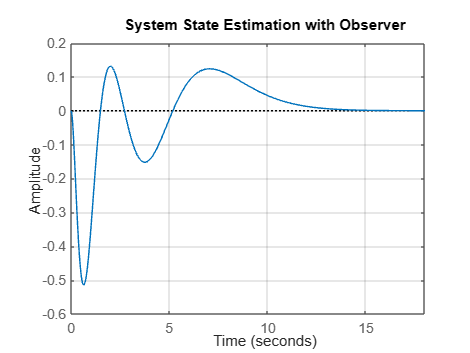

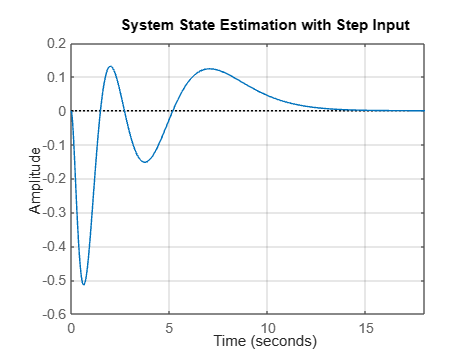

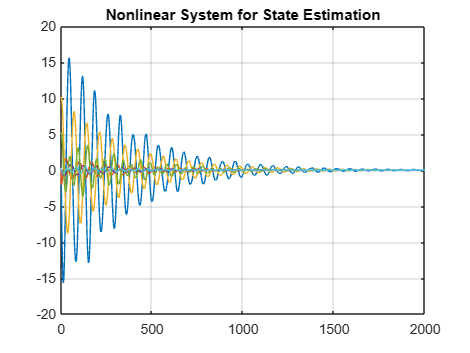

C is not observable.


C is observable.


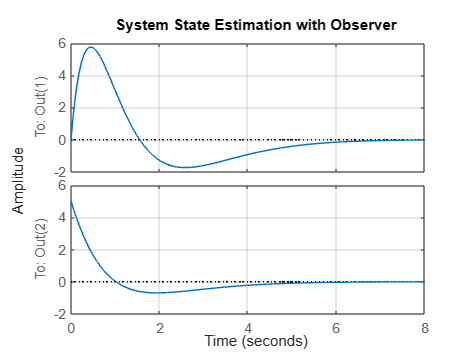

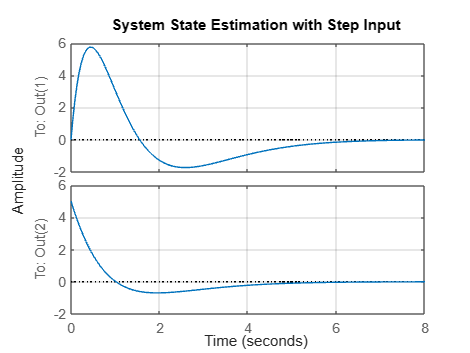

C is observable.


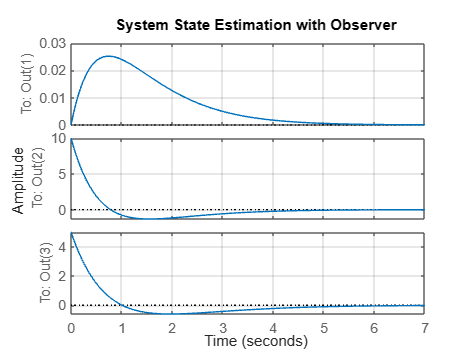

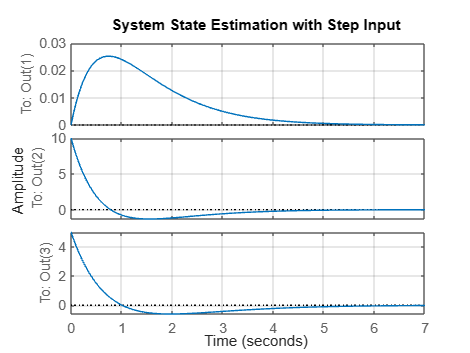


% Setup C and D Matrices
C = eye(6);

D = 0;


% Setup Gain Matrices
R = 0.0001;
Q1 = 1;
Q2 = 100;
Q3 = 1;
Q4 = 100;
Q5 = 10;
Q6 = 10;

Q = diag([Q1, Q2, Q3, Q4, Q5, Q6]);

% Find LQR Gain Matrix
[K, P, poles] = lqr(A, B, Q, R);
poles = [-1; -1.1; -1.2; -1.3; -1.4; -1.5]; % Arbitrarily change pole values

% Define output vector and check observability
C1 = [1 0 0 0 0 0]; % x(t)
C2 = [0 0 1 0 0 0; 0 0 0 0 1 0]; % (θ1(t), θ2(t))
C3 = [1 0 0 0 0 0; 0 0 0 0 1 0]; % (x(t), θ2(t))
C4 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]; % (x(t), θ1(t), θ2(t))

C_obs = {C1 C2 C3 C4};


for i=1:size(C_obs, 2)
    C_using = C_obs{i};

    % Create Observation Matrix
    O1 = obsv(A, C_using);
    if rank(O1) == size(A, 1)
        disp('C is observable.');
        % Design Luenberger observer
        L1 = place(A', C_using', poles)'; %use C4
        B_obs = [B, L1];
        D_obs = zeros(size(C_using, 1), size(B_obs, 2)); 
    
        
        % Simulate the linearized system with the observer
        A_obs = A - L1 * C_using;
        
    
        % Assuming initial observer estimates are zero
        X0_obs = [X0; zeros(6, 1)];
        
        % Create State Space Equation for State Estimation
        system_obs_behavior = ss(A_obs, B_obs, C_using, D_obs);
        
        % Plot Initial Condition with Linearized System
        figure;
        initial(system_obs_behavior, X0);
        title('System State Estimation with Observer');
        grid on;    

        % Plot Step Input with Linearized System
        figure;
        initial(system_obs_behavior, X0);
        title('System State Estimation with Step Input');
        grid on;    

        % Simulation parameters
        time_period = 0:0.01:2000;
        
        % Nonlinear feedback simulation
        [t, Y] = ode45(@(t,X) nonlinearfeedback(t, X, K, M_v, m1_v, m2_v, l1_v, l2_v, g_v, C_using, L1), time_period, X0);
        figure;
        plot(t, Y);
        title('Nonlinear System for State Estimation');
        grid on;
    
    else
        disp('C is not observable.');
    end
end

function y_dot = nonlinearfeedback(t, Y, K, M, m1, m2, l1, l2, g, C_using, L1)
    F = -K * Y;
    if size(C_using, 1) == 1
        x = [Y(1)];
    elseif size(C_using, 1) == 2
        x = [Y(1); Y(5)];
    elseif size(C_using, 1) == 3
        x = [Y(1); Y(3); Y(5)];
    end
    correction_term = L1*(x - C_using*Y);
    y_dot = zeros(6, 1);
    y_dot(1) = Y(2);
    y_dot(2) = (1/(M + m1 + m2)) * (F + (m1 * l1 * y_dot(4) * cosd(Y(3))) + (m2 * l2 * y_dot(6) * cosd(Y(5))) - (m1 * l1 * (Y(4)^2) * sind(Y(3))) - (m2 * l2 * (Y(6)^2) * sind(Y(5))));
    y_dot(3) = Y(4);
    y_dot(4) = (y_dot(2) * cosd(Y(3)) - g * sind(Y(3))) / l1;
    y_dot(5) = Y(6);
    y_dot(6) = (y_dot(2) * cosd(Y(5)) - g * sind(Y(5))) / l2;
    y_dot = y_dot + correction_term;
end
